path = dir("G:\My Drive\1. Projects\PHYS-559 Graduate Laboratory (Spring 2023)\NMR Project\Final Paper Data\0.115M\*.csv")

path = 34×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


sampleConcentration = '0.115M'

sampleConcentration = '0.115M'

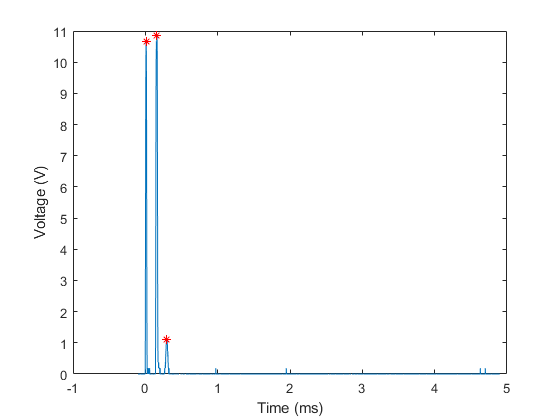

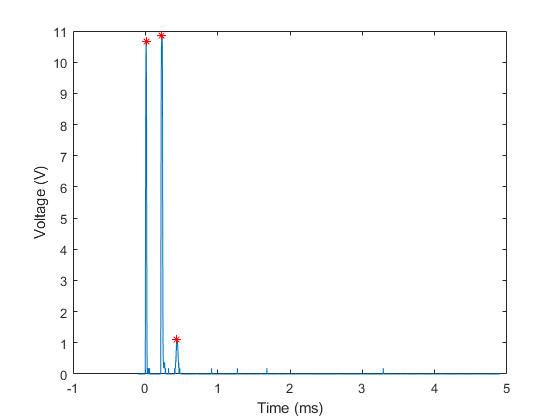

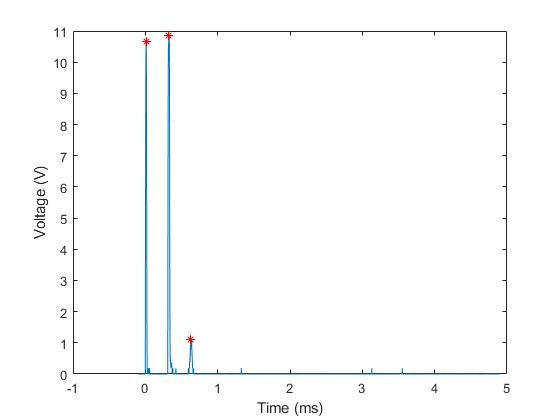

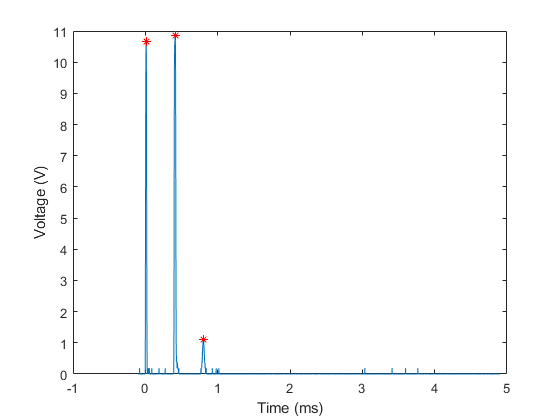

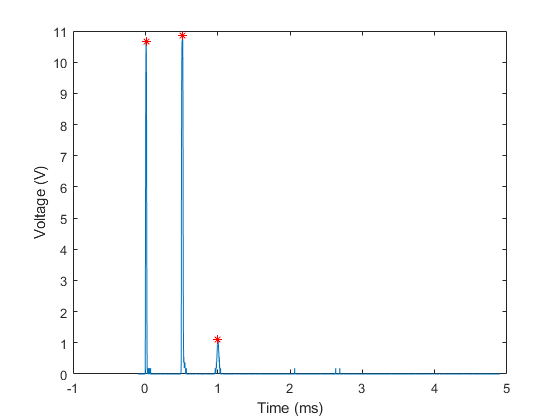

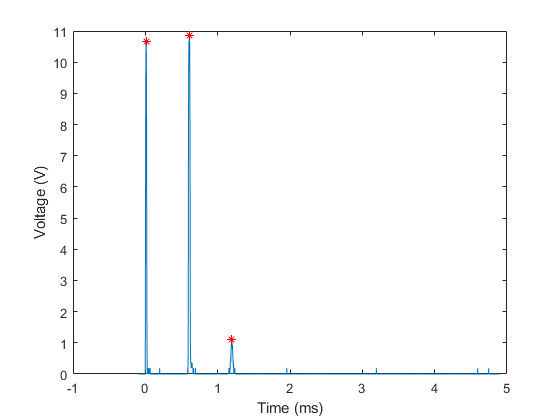

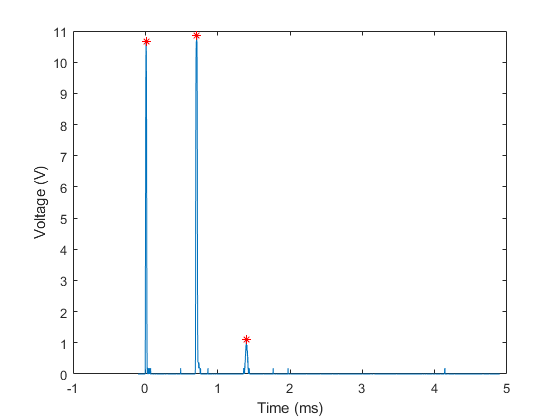

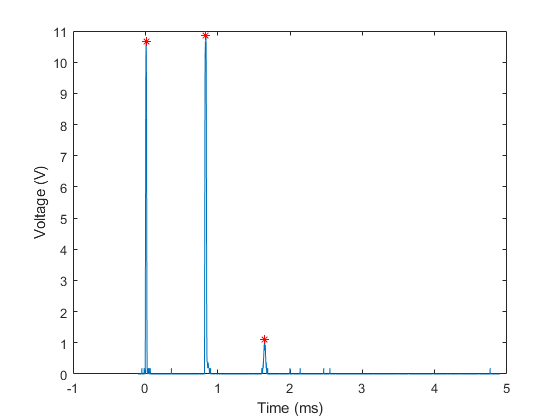

pulse_seperation =     0.1490    0.2184    0.3163    0.4015    0.5030    0.5977    0.6993    0.8246    0.9183    1.0304    1.1496    1.2809    1.4263    1.6031    1.7435         0    2.0317    2.1860    2.3673    2.5693    2.7283    2.8807    2.9996    3.1227    3.2470    3.4100    3.6643    3.8853    4.0988


spinEchoAmp =     1.1220    1.1220    1.1220    1.1220    1.1220    1.1220    1.1220    1.1220    0.9350    0.9350    0.9350    0.9350    0.9350    0.7480    0.7480         0    0.7480    0.7480    0.5610    0.5610    0.5610    0.5610    0.5610    0.5610    0.5610    0.5610    0.3740    0.4212    0.4212


[pulse_seperation, spinEchoAmp] = NMRdataAnalysis(path,sampleConcentration)

logSpinEchoAmp = log(spinEchoAmp)

logSpinEchoAmp =     0.1152    0.1152    0.1152    0.1152    0.1152    0.1152    0.1152    0.1152   -0.0672   -0.0672   -0.0672   -0.0672   -0.0672   -0.2903   -0.2903      -Inf   -0.2903   -0.2903   -0.5780   -0.5780   -0.5780   -0.5780   -0.5780   -0.5780   -0.5780   -0.5780   -0.9835   -0.8646   -0.8646


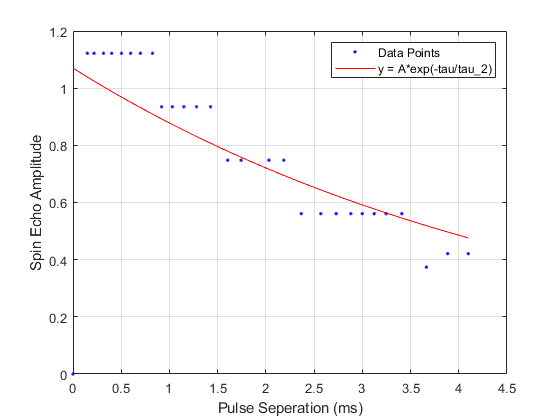

fitresult =      General model:
     fitresult(t) = A*exp(-t/t_2)
     Coefficients (with 95% confidence bounds):
       A =        1.07  (0.8891, 1.251)
       t_2 =       5.062  (2.446, 7.679)

gof = struct with fields:
           sse: 1.4276
       rsquare: 0.4225
           dfe: 27
    adjrsquare: 0.4011
          rmse: 0.2299


[fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)

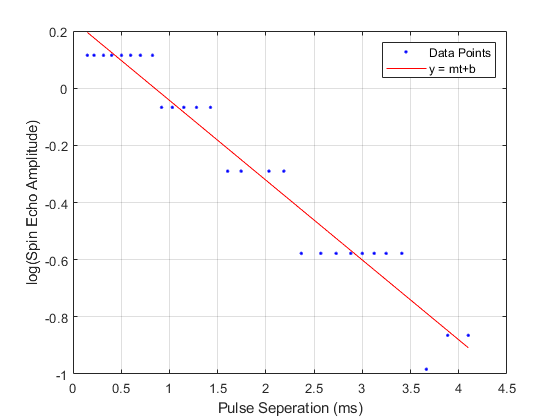

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
       where x is normalized by mean 1.859 and std 1.232
     Coefficients (with 95% confidence bounds):
       p1 =      -0.344  (-0.376, -0.312)
       p2 =     -0.2826  (-0.314, -0.2512)

gof = struct with fields:
           sse: 0.1701
       rsquare: 0.9494
           dfe: 26
    adjrsquare: 0.9475
          rmse: 0.0809


[fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)

function [fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)
%CREATEFIT(PULSE_SEPERATION,SPINECHOAMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : pulse_seperation
%      Y Output: spinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:36:59


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( pulse_seperation, spinEchoAmp );

% Set up fittype and options.
ft = fittype( 'A*exp(-t/t_2)', 'independent', 't', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.0461713906311539 0.0971317812358475];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'Exponential Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = A*exp(-tau/tau_2)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'Spin Echo Amplitude', 'Interpreter', 'none' );
grid on
end
function [fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)
%CREATEFIT1(PULSE_SEPERATION,LOGSPINECHOAMP)
%  Create a fit.
%
%  Data for 'Linear Fit' fit:
%      X Input : pulse_seperation
%      Y Output: logSpinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:39:47


%% Fit: 'Linear Fit'.
[xData, yData] = prepareCurveData( pulse_seperation, logSpinEchoAmp );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% Plot fit with data.
figure( 'Name', 'Linear Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = mt+b', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'log(Spin Echo Amplitude)', 'Interpreter', 'none' );
grid on
end

